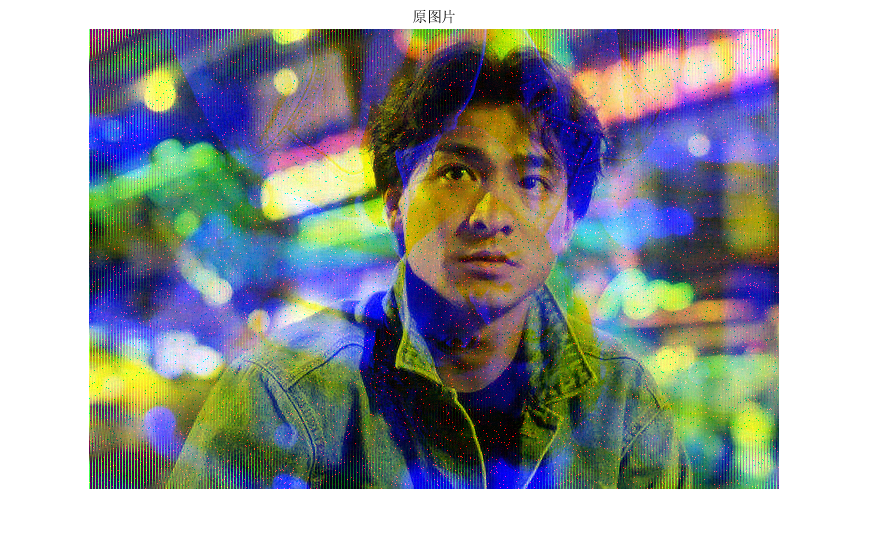

clc;
clear;
I=imread("12-刘德华.tif");
I=im2double(I);
figure
imshow(I);
title("原图片");

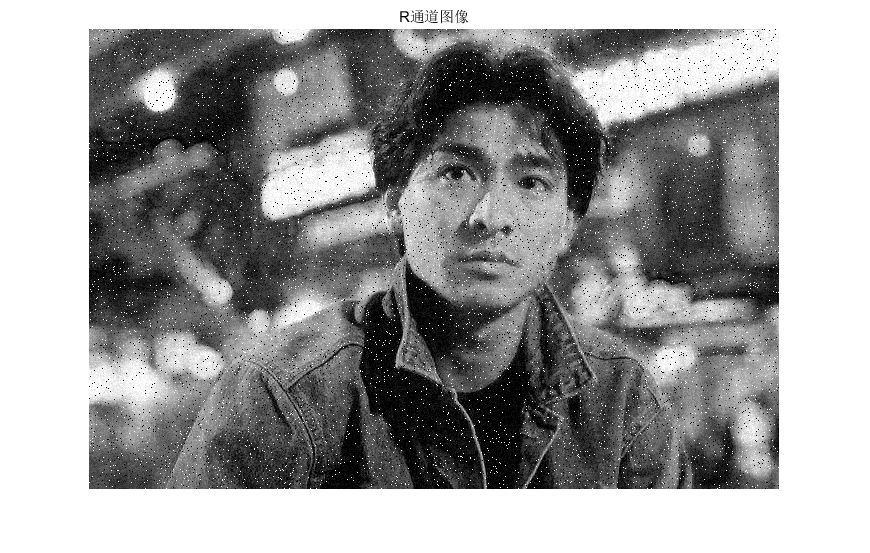

%取出RG通道
I_R=I(:,:,1);
I_G=I(:,:,2);
%绘制R通道图像
figure
imshow(I_R);
title('R通道图像');

disp('R通道噪声为椒盐噪声，选用中值滤波器消除');

R通道噪声为椒盐噪声，选用中值滤波器消除


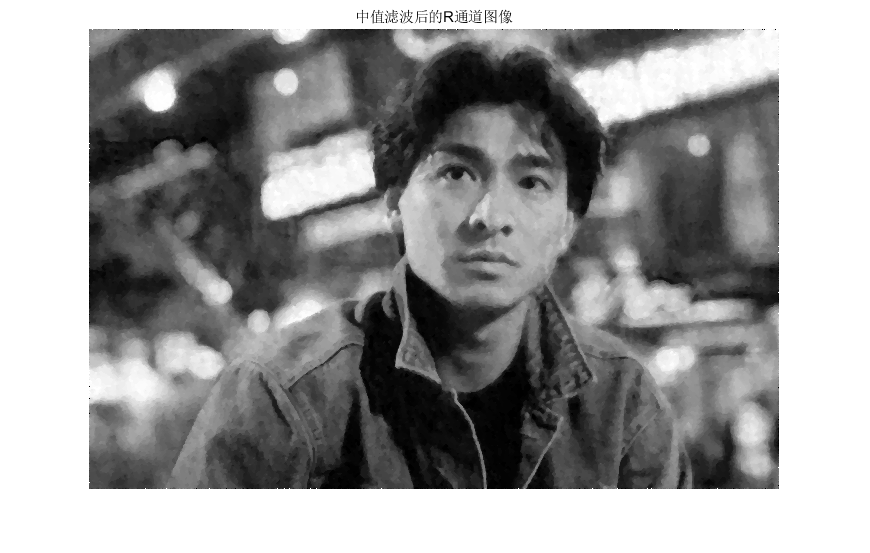

[m,n]=size(I_R);
for i=2:m-1
    for j=2:n-1
        mat=I_R(i-1:i+1,j-1:j+1); %取出以该像素点为中心的3*3矩阵
        mat1=mat(:);              %将矩阵变成向量
        s=sort(mat1);             %排序
        I_R(i,j)=s(5);            %取出中值
    end
end
%绘制结果
figure
imshow(I_R);
title('中值滤波后的R通道图像');

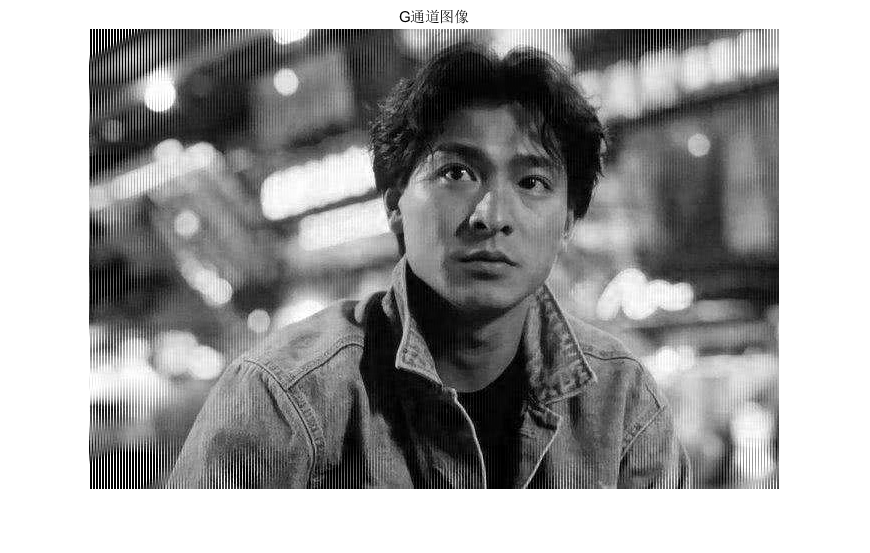

%绘制G通道图像
figure
imshow(I_G);
title('G通道图像');

disp('G通道噪声为周期噪声，用高斯低通频域滤波器')

G通道噪声为周期噪声，用高斯低通频域滤波器


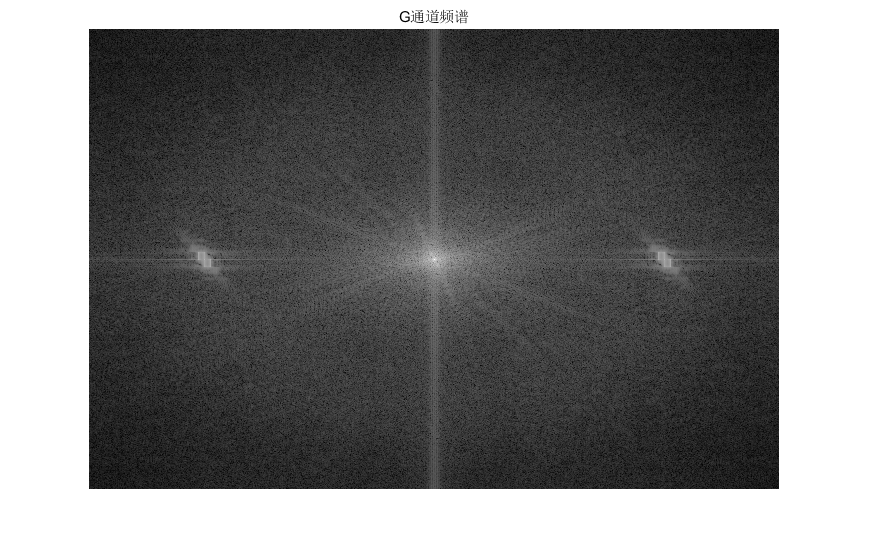

%求G通道的频谱
Y=fftshift(fft2(I_G));
%对频谱进行对数变换以便观看
Y_val=log(1+abs(Y));
Y_val=Y_val/max(Y_val,[],"all");%归一化
[row,col]=size(I_G);
figure
imshow(abs(Y_val),[]);
title('G通道频谱');

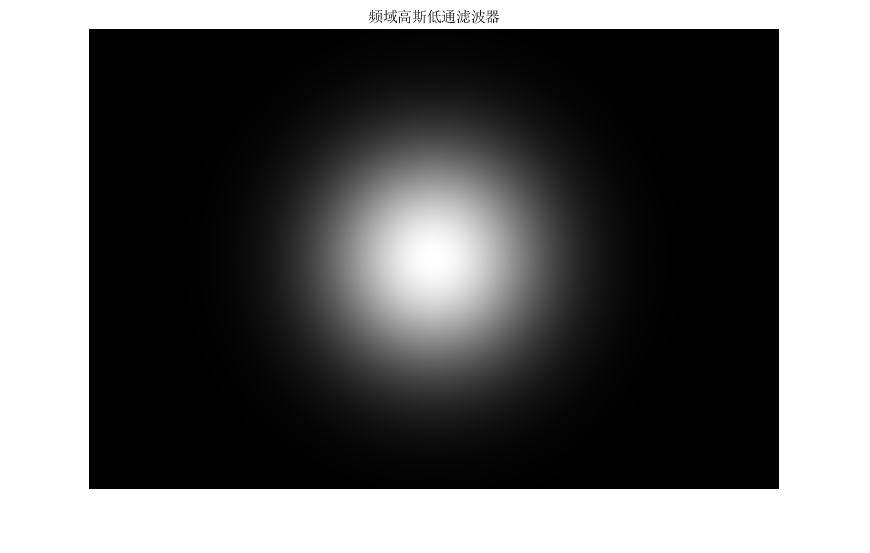

%图像中心点
M0=row/2;
N0=col/2;

%高斯低通滤波器的频域表示为：
%         H(u,v)=exp(-D(u,v)^2/(2*delta1^2))
%其中D(u,v)为(u，v)到中心点的距离,delta1为方差

delta1=75;     %设置方差
%求高斯低通滤波器
for x=1:row
    for y=1:col
        d2=(x-M0)^2+(y-N0)^2;  %计算点（x,y）到中心点的距离的平方
        H_gauss(x,y)=exp(-d2/(2*delta1^2)); %计算高斯低通滤波
    end
end
%绘制高斯低通滤波器
figure
imshow(H_gauss);
title("频域高斯低通滤波器");

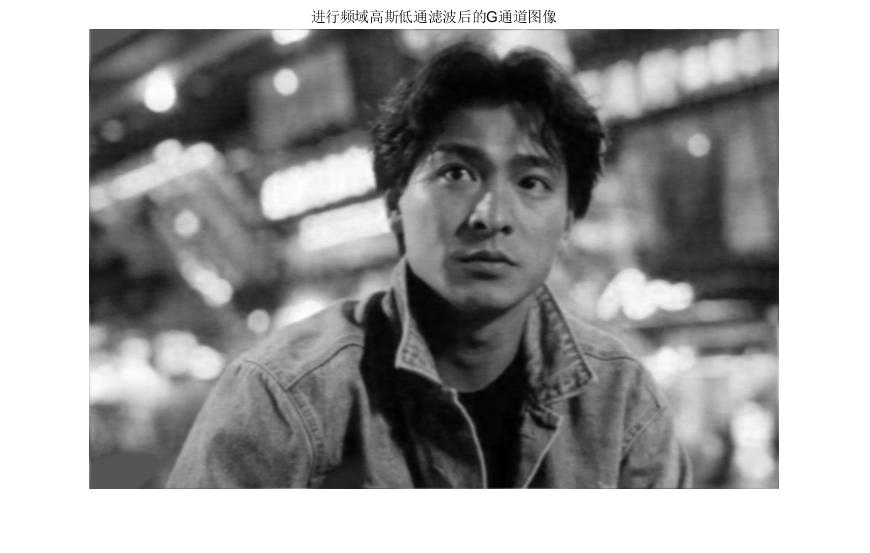

%对图像滤波
Y_filt=Y.*H_gauss;
%进行傅里叶反变换
I_guass=abs(ifft2(ifftshift(Y_filt)));
%绘制结果
figure
imshow(I_guass);
title('进行频域高斯低通滤波后的G通道图像');

%储存
imwrite(I_R,'中值滤波后的R通道图像.jpg',"jpg");
imwrite(I_guass,'进行频域高斯低通滤波后的G通道图像.jpg',"jpg");


